# Worksheet 5, Part 1 / 4: Beyond "A Single Value"

*Author: *Zachary del Rosario, Fall 2022

*Important Note:* Worksheet 5 comes to you in **four**** parts**; `worksheet5_part1_assignment.mlx`, `worksheet5_part2_assignment.mlx`, and `worksheet5_part3_assignment.mlx`, and `worksheet5_part4_assignment.mlx`

*Learning Objectives:* As a result of working through this notebook, you will learn:

- Why viewing the world *solely* in terms of "single values" is foolish and dangerous.

- An alternative approach to go beyond single values: probability modeling.

- Fundamentals of probability theory: Random variables, distributions, and summaries.

### Additional Files

Make sure to download these additional files from Canvas and place them in the same folder as this worksheet:

- `simulate_absir.m`

## Jigsaw Activity: What's wrong with "A Single Value"?

To begin this worksheet, we are going to start with an activity that relies on the reading you (hopefully!) all completed. This is called a *jigsaw* in educational circles, because we are going to put together the different "pieces" from the readings. At least one person in your group (possibly more) should have read each of the following:

- Gould (1991) "The Median Isn't the Message" [link](https://journalofethics.ama-assn.org/article/median-isnt-message/2013-01)

- Trufelman (2016) "On Average" [link](https://99percentinvisible.org/episode/on-average/)

- Rose (2013) "The Myth of Average" [link](https://www.youtube.com/watch?v=4eBmyttcfU4)

### Motivating Questions

As mentioned in the pre-worksheet assignment "Reading Homework: Jigsaw Preparation," we have a few motivating questions for this discussion:			

- Why do you think people focus on single numbers, such as the mean or median?

- What are the limitations / dangers of focusing on a single number, such as the mean or median? 

- What are some specific examples of going “beyond” a single value? What benefit did that approach achieve?

- What would be another context where a single value would be a dangerous approach?

Our goal as a group is to come to a satisfactory answer for all of these questions. To do so, we'll need to put our heads together!

### Exercise 1 / 5: Jigsaw Activity Instructions

This activity will take about 16 minutes of in-class time. Follow these steps:

- (30 seconds) Count off from 1 to 4. Your number corresponds to the Motivating Question you will be responsible for answering & presenting to the full class.

- (2 mins) Whoever read the Gould (1991) (Reading Group 1) article: Summarize the article for your tablemates

- (2 mins) Whoever read / listened to the Trufelman (2016) (Reading Group 2) podcast episode: Summarize the story for your tablemates

- (2 mins) Whoever watched the Rose (2013) (Reading Group 3) TEDx talk: Summarize the video for your tablemates

- (5 mins) Among your table, come up with an answer for each of the four Motivating Questions. Be ready to discuss your answers with the full class!

- (5 minutes) The instructors will call on different tables to provide their answers to each of the Motivating Questions. If your table is called upon, be ready to answer the Motivating Question corresponding to your count-off number. *Hint:* Write your answers down first (below) so you can just read them during the discussion!

Why do you think people focus on single numbers, such as the mean or median?

- *(Write your response here; collaborate with your tablemates!) *They are simple to calculate and apply, and it is easy to assume that most of whatever you are measuring falls into this single number.

What are the limitations / dangers of focusing on a single number, such as the mean or median?

- *(Write your response here; collaborate with your tablemates!) *Since most people do not fit the average, items created based on the average will have no use or will do their job poorly. Incorrect information can also be spread, leading to people having a false sense of certain aspects of their health and life. What works for someone on one axis will probably not work for them on all axis'.

What are some specific examples of going “beyond” a single value? What benefit did that approach achieve?

- *(Write your response here; collaborate with your tablemates!) *Using a histogram allows you to better see the spread and incorporate standard deviation. Gould, a man who was diagnosed with cancer, decided to not take the average survival time as fact and his positive outlook most likely led to him living much longer than expected.

What would be another context where a single value would be a dangerous approach?

- *(Write your response here; collaborate with your tablemates!) *College admissions, where they just base all your worth on a single number, when in reality there is a lot more to people that can't be represented in this number. Car safety is another example, as most people who are above the average cannot safely fit in a car.

## "A Single Value" in Disease Transmission Modeling

Back in Worksheet 4, in addition to introducing graph theory to model social connections, I also *quietly* changed the model from deterministic to random. Why did I do that? Let's take a closer look....

Randomness enters into the agent-based SIR model at these lines in the `simulate_absir.m` code:

% NOTE: The following code is copied from the simulate_absir.m code from
% Worksheet 4. Since it can't operate outside the context of the internal
% action() function, I've commented it out in this block.

% % Compute infection probabilities based on the social graph
% v_eff = infection_rate * M * I; % Compute "infection effect"
% v_pr = v_eff ./ (1 + v_eff);    % Transform "infection effect" into a probability
%         
% % Draw random values
% v_infect = rand(dim, 1) <= v_pr;           % Simulate a random variable to decide infections
% v_recover = rand(dim, 1) <= recovery_rate; % Simulate a random variable to decide recoveries

The "infection effect" is the vector `v_eff`. Hopefully `v_eff` is familiar; that's just a quantitative measure of how much infection exposure each individual in the model receives at each timestep in the model. This vector accounts for things like the social connectivity of individuals (through the adjacency matrix `M`), the current infection status of everyone in the simulation `I`, and the overall infectivity of the disease `infection_rate`. All of these contributions (hopefully) make sense.

Where things start to get weird is at this line:

% v_pr = v_eff ./ (1 + v_eff);    % Transform "infection effect" into a probability

This line converts the "infection effect" into a *probability*: a value between 0 and 1 that represents how probable it is that each individual becomes infected at that particular timestep. Why did I choose to design the model this way? There are two reasons:

### Reason 1. A deterministic model is boring (Bad reason!)

First a confession: I made this choice *partly* because a deterministic model for agent-based SIR is *boring*.

To see this, we'll need to reason a bit about the structure of the model.

### Exercise 2 / 5

Consider the equation


$$p = \frac{v_{\text{eff}}}{1 + v_{\text{eff}}}$$


What are the lower and upper bounds allowed for `v_eff` in order for the probability value $p$ to live between $[0, 1]$? Answer the questions below.

*Hint*: The special value `inf` in Matlab corresponds to positive infinity $+\infty$.

% TODO: Determine the lower and upper limits for v_eff
v_eff_lo = 0
v_eff_up = inf

% NOTE: Do not edit this; use this to check your work
assert(v_eff_lo / (1 + v_eff_lo) == 0, 'Your v_eff_lo is incorrect');
assert(v_eff_up > realmax, 'Your v_eff_up is incorrect');

- If we set `infection_rate` to an enormous value (say 1,000,000), what will that tend to do to the probability values `v_pr`?

-  *(Write your response here) *They wil tend to go towards 1.

If we only have probability values of 0 or 1, then the system is *deterministic*. The outcomes of a "random" draw will be guaranteed to come up a certain way:

v_infect = rand(2, 1) <= [

v_eff_lo = 0

    0; % This will *definitely* lead to *no infection*

v_eff_up = Inf

    1  % Thiw will *definitely* lead to *an infection*
]

To see how the agent-based SIR model would behave if it were deterministic, we can simply crank up the `infection_rate` to an enormous value. This will drive the probability values `v_pr` to be either 0 or 1. Let's see what happens if we make this change:

% Set up a simple homogeneous system
n_pop = 100;
M = ones(n_pop, n_pop) - eye(n_pop);
Iv0 = zeros(n_pop, 1);
Iv0(50) = 1; % Put Patient 0 in the "middle" of the population

% Set an *enormous* infectivity to create a deterministic model
infection_rate = 1e6;


v_infect = 2×1 logical array
   0
   1


% Simulate the model
[~, Ih, ~] = simulate_absir(M, Iv0, 5, infection_rate, 0);

% Visualize the full infection history
figure(); spy(Ih)
xlabel('Timestep')
ylabel('Infection History')
pbaspect([2 1 1])

Notice that *everyone*, in the *entire population,* becomes infected *instantaneously*. That's super-boring!

The real problem with this modeling approach is that **we have no way of varying the rate of infection.** If contact with an infected person is deterministic, then there is no way to tune the infectivity of the disease. Tuning infectivity was not just how we represented the "infective power" of the disease, it's also how we modeled differences across social connections, e.g., to model masking vs podding.

### Reason 2. A deterministic model is patently absurd (Better reason!)

The other (better) reason for a random agent-based model over a deterministic agent-based model is that **a deterministic model assumes there is some magic "single value" that will determine a person's infection status.** As we saw above, there are *many *reasons why we should be skeptical of a single value approach as the "one true way" of doing analysis / modeling. But let's take a closer look at why this is a bad idea for determining the results of an infection exposure.

Let's imagine that a person (call them Person 1) is exposed to a disease (say, Influenza). In order to *deterministically* model the outcome of this exposure, we first need to know *a few* facts about Person 1:

**STOP AND DISCUSS - What are some factors you might need to know about someone in order to model the outcome of this exposure**

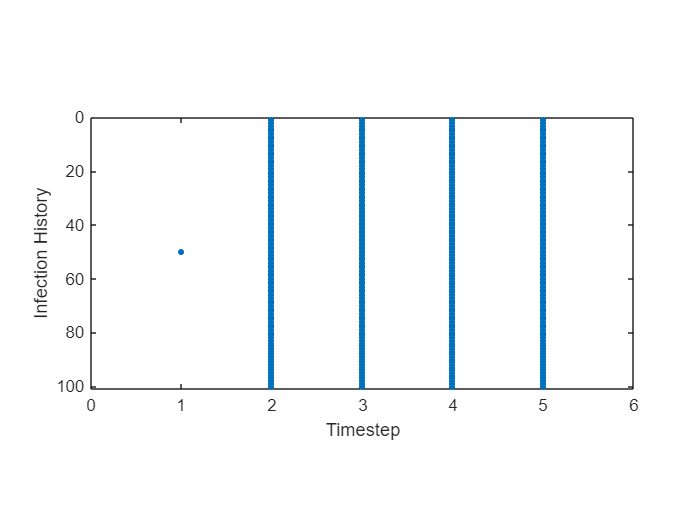

% List out relevant factors for Person 1
person1 = table;
person1.infected = 0;            % Infection status at time of exposure

% Lifestyle factors; a person's health will contribute to their ability to
% fight off an infection
person1.age = 22;                % Age at time of exposure
person1.bmi = 25;                % Body mass index
person1.exercise_per_week = 5;   % In hours
person1.cigarettes_per_week = 1;

person1.drinks_per_week = 2.5;
% ... plus dozens of other factors

% Other infections (comorbidities); the presence of other diseases will
% suppress a person's ability to fight infection
%
% via Holland-Frei Cancer Medicine. 6th edition.
% Kufe DW, Pollock RE, Weichselbaum RR, et al., editors.
% Hamilton (ON): BC Decker; 2003.
person1.acute_leukemia = 0;
person1.aplastic_anemia = 0; 
person1.hairy_cell_leukemia = 0;
person1.chronic_lymphatic_leukemia = 0;
person1.multiple_myeloma_Neisseria = 0;
person1.Hodgkin_disease = 0;
person1.AIDS = 0;
person1.Bone_marrow_transplant_recipient = 1;
person1.breast_cancer = 0;
person1.lung_cancer = 0;
person1.Gynecologic_malignancy = 0;
% ... plus dozens of other comorbidities

% Environmental factors; similar to lifestyle factors, but these are
% largely outside a person's control
%
person1.local_air_quality = 95;     % Score out of 100
person1.local_water_quality = 85;   % Score out of 100
person1.sleep_quality = 65;         % Score out of 100
% ... plus dozens of other factors

% Genetic factors; a person's genetic makeup is known to affect their
% susceptibility to disease
%
% via https://virologyresearchservices.com/2019/07/29/susceptibility-to-virus/
person1.polymorphism_hRIP = 1;        % polymorphism of hRIP gene
person1.polymorphism_DENV_locus1 = 0; % polymorphism associated with DENV pathogenesis, locus 1
person1.polymorphism_DENV_locus2 = 0; % polymorphism associated with DENV pathogenesis, locus 2
% ... plus 20,000 to 25,000 other genes

% Print the table...
person1

This is a *subset *of the thousands (perhaps millions) of factors that might be relevant to how the infection exposure will play out. And this is just the table for *one single person; *we would need to assemble a dataset for every individual in our proposed model. If we wanted to model a made-up scenario, we would need to make decisions about these millions of factors for each person in the simulation. If we wanted to model a real-world scenario, we would need to conduct an *incredibly invasive* survey of the population we want to study (likely thousands of people).

We *could* assume an average value for many of the values in this table, but *hopefully* you now understand why that is also a terrible idea.

All of this does not even touch on how we would *use* the information in this proposed table. For instance, scientific knowledge of the link between genetic factors and disease susceptibility is [extremely limited](https://virologyresearchservices.com/2019/07/29/susceptibility-to-virus/), in part because it would be *deeply unethical* (not to mention impractical!) to manipulate a person's genome to test their susceptibility to an infection. But even if we did have *some* understanding of these factors, how would we put them together?

% Assume the person is not infected, unless one of the following criteria
% is met...
person1_infected = 0;

if person1.infected
    % Easy case
    person1_infected = 1;
elseif person1.age > 75
    % Advanced age will limit one's ability to fight infection, but is this
    % the right threshold?
    person1_infected = 1;
elseif (person1.age > 65) && (person1.bmi > 24.9)
    % BMI may reduce the age threshold...?
    person1_infected = 1;
elseif (person1.age > 75) && (person1.bmi > 24.9) && (person1.exercise_per_week >= 5)
    % But maybe exercise could offset that effect?!?!
    person1_infected = 0;
    

person1 = 1×23 table
    infected    age    bmi    exercise_per_week    cigarettes_per_week    drinks_per_week    acute_leukemia    aplastic_anemia    hairy_cell_leukemia    chronic_lymphatic_leukemia    multiple_myeloma_Neisseria    Hodgkin_disease    AIDS    Bone_marrow_transplant_recipient    breast_cancer    lung_cancer    Gynecologic_malignancy    local_air_quality    local_water_quality    sleep_quality    polymorphism_hRIP    polymorphism_DENV_locus1    polymorphism_DENV_locus2
    ________    ___    ___    _________________    

    % THIS LIST WOULD CONTINUE FOREVER....
    
end

The key problem here is that **we cannot model the outcome of an infection exposure deterministically. There is no sensible way to combine all this information into a yes/no answer.**

### An Alternative Approach: Embrace Variability

Clearly, a deterministic approach to an agent-based model for disease transmission is a foolish goal. However, this doesn't necessarily endorse the random approach. Why would modeling the outcome of disease transmission randomly make sense? The key shift in mindset is to *embrace variability*.

*Variability* is a fact of life. No two people are identical across all the variables listed above. So rather than try to model outcomes with single values, why not *embrace* this fact and think about outcomes in terms of variability? *This is fundamentally what a random approach to modeling does: embrace variability.*

To close this discussion, we actually *could* use information like that in the table `person1` above. Epidemiologists make this kind of assessment all the time! However, they make the assessments in a way that respects variability: by giving *rates* (essentially, probabilities), rather than claiming that any given person "will" contract a disease. For instance, the following plot shows how the rate of cancer varies with the age of the patient at the time of diagnosis:

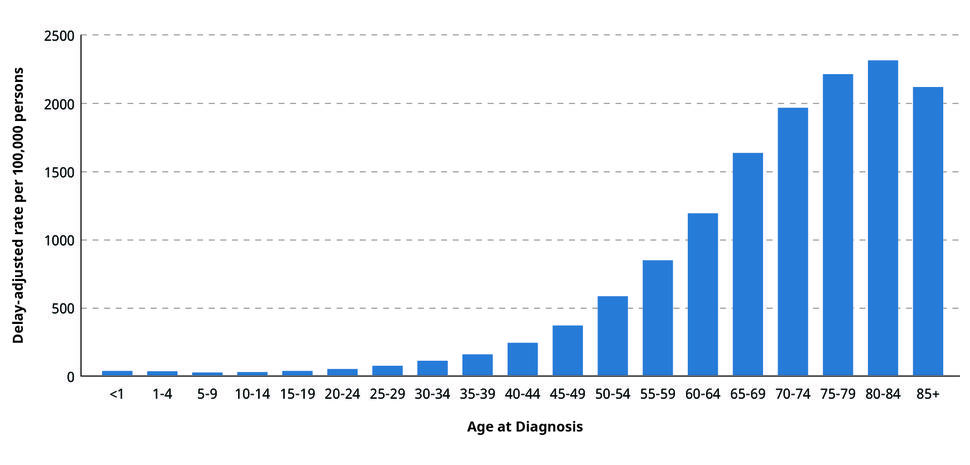

*Age and Cancer Risk was originally published by the National Cancer Institute.*

There is no way to guarantee whether a person in a particular age-range will or will not get cancer. But we can study large groups of similar people and quantify rates. We can even look for patterns in these rates across multiple variables, giving us even more information! This is known as *statistical modeling*, and while it's not a topic we'll cover in ModSim, it *is* a very cool area for future study.

## Probability Modeling: How to go beyond "a single value"

We've talked about the *limitations* of a single value understanding of quantities, but what is the alternative? We'll use *probability modeling* as our alternative. To make sense of this, we need to draw a distinction between *deterministic quantities* and *random quantities*, specifically in how they relate to models.

**Deterministic quantity:** A deterministic quantity is one that takes a single value. Note that the quantity can *vary*, but it will take the same value(s) each time we run the model.

- Example: The age of a person in the model; this is a parameter that we will fix in order to run the model.

- Example: The current time of the simulation; this variable represents the current state of the model, and will vary (increment by 1) in an obvious way.

- Example: The current number of infected persons; this variable represents the current state of the model, and will vary in a *non-obvious way* (we need the model to determine this!), but for a compartmental SIR model, it will vary in a *deterministic way.*

**Random quantity:** A random quantity is one that can take different values. The quantity will be determined ("realized") each time we run the model. While a random quantity is unpredictable, it is not "just random"—random quantities have predictable properties in-aggregate (a "sample") determined by a *distribution*.

- Example: The outcome of an infection exposure. This can only take one of two values (Yes or No; True or False), but the outcome of any infection exposure is impossible to determine with 100% certainty. Instead, we can use a variety of factors to determine the probability of infection, such as the number of exposures (through social connectivity) and the infectivity of the virus (through `infection_rate`).

- Example: Whether or not a person will be diagnosed with cancer. For any specific form of cancer (say, abdominal mesothelioma, as in Steven Jay Gould's story), a person either does—or does not—have the cancer (perhaps in one of a few stages). As we can see above, the rate of cancer diagnosis varies dramatically with age, as people under the age of 20 are very unlikely to have any form of cancer. However, as a person ages they are more *probable—but not guaranteed—*to develop a cancer.

### Deterministic or Random: Making modeling choices

Deciding which quantities should be deterministic and which should be random in our model is another important step of the modeling process. Some quantities (such as time) will obviously be deterministic ("time marches forward") while others will clearly be best to model as random (e.g., the outcome of an infection exposure). However, there will be a lot of grey area between these two decisions. Generally, phenomena that are too complex to model as deterministic are good candidates to model as random.

There are other quantities that we cannot know exactly, but that we may want to represent as deterministic quantities for convenience. For instance, what is the "true" or "correct" `infection_rate` in our agent-based SIR model? Clearly this `infection_rate` abstracts many complex phenomena, such as the health, lifestyle, and genetic factors described above. But does that mean `infection_rate` should *also* be modeled as a random quantity? The *correct* answer is "it depends on our modeling question." If our modeling question does not specifically relate to differences between individuals—if we can "get away" with treating people as identical for the purposes of answering our question—then it may be prudent to keep `infection_rate` simple by modeling it as a single deterministic value. Even if we need to represent different groups of people, we might make `infection_rate` only slightly more complex by using different deterministic values for different individuals or for different social connections—we essentially did this when we modeled masking vs podding.

One example of when we might want to model `infection_rate` as a random quantity is if we were interested in how masking *compliance* would affect the spread of a disease. If we were to model the susceptibility of an individual to infection based on whether or not they wore a mask, we might introduce a random quantity that would switch "on" or "off" masking on a per-individual basis. In this case, a random quantity would help us model this mask vs no-mask phenomenon, which would be especially helpful as the decision whether or not to wear a mask is very complex (depending on ideology, current infection rates, social pressures, and so on).

Let's practice making decisions about deterministic or random quantities in a model:

### Exercise 3 / 5

Suppose we were modeling the spread of a viral—but deliberatly misinformative—meme across a social network (represented by a graph). Our modeling question is "What kinds of content moderation strategies will help prevent the spread of misinformation across a social network?" We will model these content moderation strategies as a modification to the weights of the network *while* the model is running.

- The *initial* strength of a social connection between two individuals in the model. Deterministic or random, and why?

-  *(Write your response here) *Deterministic because the inital strength should not change so we know that the initial strength of connection is not the possible casuse of our results.

- The *updated* strength of a social connection between two individuals in the model, in response to the spread of the meme. Deterministic or random, and why?

-  *(Write your response here) *Random because it will randomly change every realization depending on how the meme spreads.

- The current time in the simulation. Deterministic or random, and why?

-  *(Write your response here) *Deterministic because we are assuming the timestep is the same.

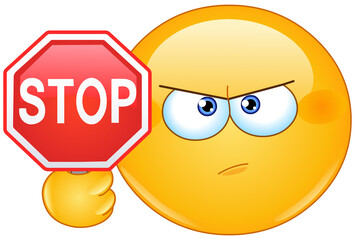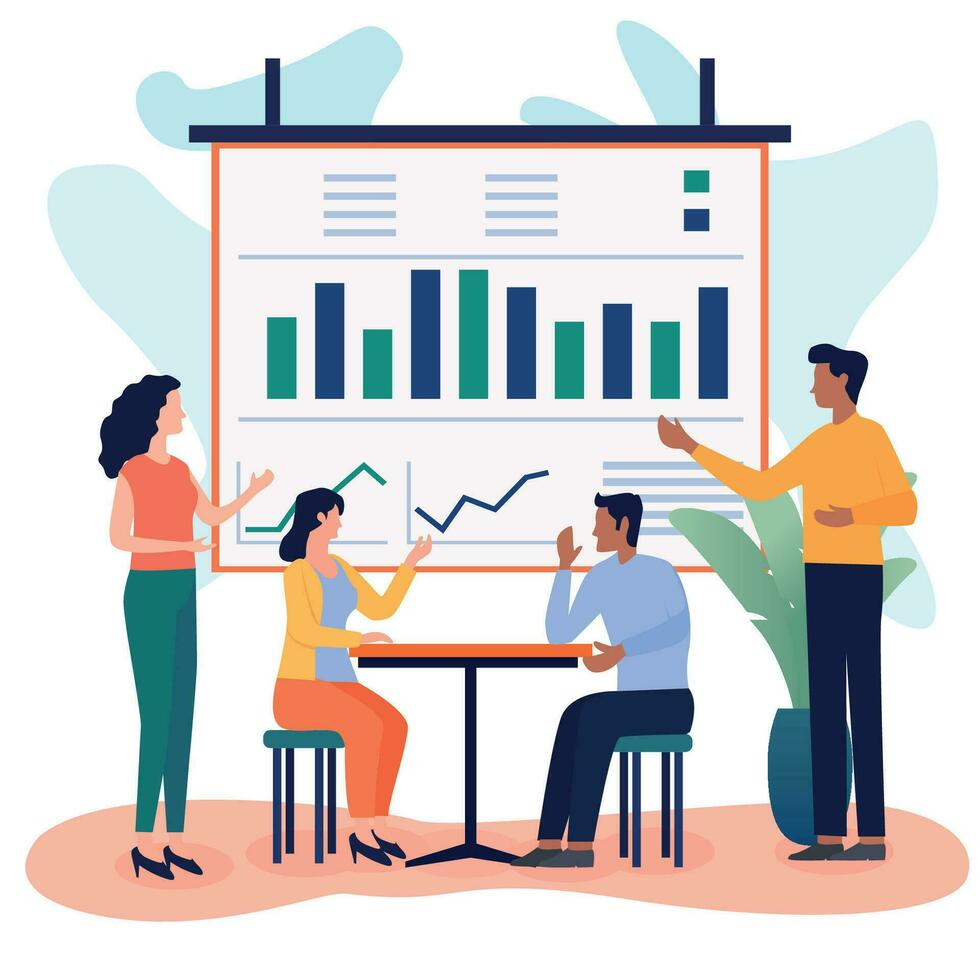

**STOP & DISCUSS: Compare your answers with your tablemates - did you all answer each question the same way? If so, did you have the same reasoning?**

Classifying quantities as deterministic or random is an *important* early step in building a model, but there is much more work we need to do to define random quantities. So let's talk about how to define random quantities using *probability theory*.

## Defining Random Quantities: Fundamentals of Probability Theory

Random quantities (also called [*random variables*](https://en.wikipedia.org/wiki/Random_variable)) are *defined* by a mathematical object called a *distribution*. A distribution is a quantitative description of the relative frequency with which different values will occur. Distribution functions allow us to quantify these rates in terms of *probability*.

*Note*. Somewhat confusingly, a *random variable* is sometimes *called* a function. This is a very mysterious (and unintuitive) way to understand what a random quantity is. I prefer to think of a random variable as a quantity that can take multiple values; one that *has* a function called a "distribution" that determines the relative frequency of those different values.

For instance, let's imagine we are flipping coins. A fair coin would have equal probability of landing with Heads or Tails facing up:

% Visualize the PMF; a fair coin
x = categorical({'Heads', 'Tails'});
y = [0.5, 0.5];
figure()
bar(x, y);
xlabel('Coin Outcome')
ylabel('Probability of Outcome')
title('A Fair Coin')
ylim([0, 1])

This plot is of the *probability mass function* (PMF) of the fair coin random variable. It tells us that if we were to flip an *infinite* number of coins, then 50% of them would land with Heads-up, and the other 50% would land with Tails-up.

An *unfair* coin would have uneven odds; the probabilities would not be equal:

% Visualize the PMF; an unfair coin
x = categorical({'Heads', 'Tails'});
y = [0.25, 0.75];
figure()
bar(x, y);
xlabel('Coin Outcome')
ylabel('Probability of Outcome')
title("An Unfair Coin (Cheater's Coin!)")
ylim([0 1])

One of the key properties of probability is that probabilities *must sum to one* across the space of possible values, called the *sample space*. For instance, the sample space $S$ for the coin is


$$S = \{H, T\}$$


The PMF for the coin $f_{\text{Coin}}(x)$ must then be a function whose output values sum to one. We can write the PMF for a general coin as


$$f_{\text{Coin}}(x) = \left\{\matrix{x = H & p \cr x = T & 1 - p}\right.$$


For the fair coin, we have $p = 0.5$. For the unfair coin, we have $p = 0.25$. The value $p$ is called a *parameter* of the distribution; it is a *deterministic* quantity that tells us about the properties of the *random* quantity.

Part of the complexity of random variables is that we need to make a decision about the sample space (possible values) *and* their relative frequencies (probabilities associated with each value). For instance, if we talk about a six-sided die, we need a sample space that goes from 1 to 6.

% Visualize
x = 1:6;
y = unidpdf(x, 6);
figure()
bar(x, y);
xlabel('Die Outcome')
ylabel('Probability of Outcome')
ylim([0 1])

This would be a *fair* die, because all of the sides have an equal probability of landing up. Note also that the probability associated with each face is quite a bit smaller than the 50% we saw with the (fair) coin. This is because the probability needs to be "distributed" across all the possible outcomes in the sample space.

Coins and dice are natural first examples of quantities we might *model* as random. But note that these physical objects are not *inherently random!* For instance, magicians have a variety of tricks to control the way a coin is tossed to *guarantee* that it lands on a particular face (e.g., by creating the [illusion of flipping](https://www.youtube.com/watch?v=A-L7KOjyDrE)). We use random variables to model phenomena when the outcome is uncertain, such as when we flip a coin without playing any "tricks."

For an example of a random variable more closely related to our modeling questions, let's consider a model for the number of infections resulting from a single infected person. The [poisson distribution](https://en.wikipedia.org/wiki/Poisson_distribution) is frequently used to model the number of events that occur in a specified interval of time (say, the duration of a timestep in our model). The poisson distribution (pronounced like "pwa sawn") is defined by a single parameter, usually denoted by $\lambda$ (a greek lambda).

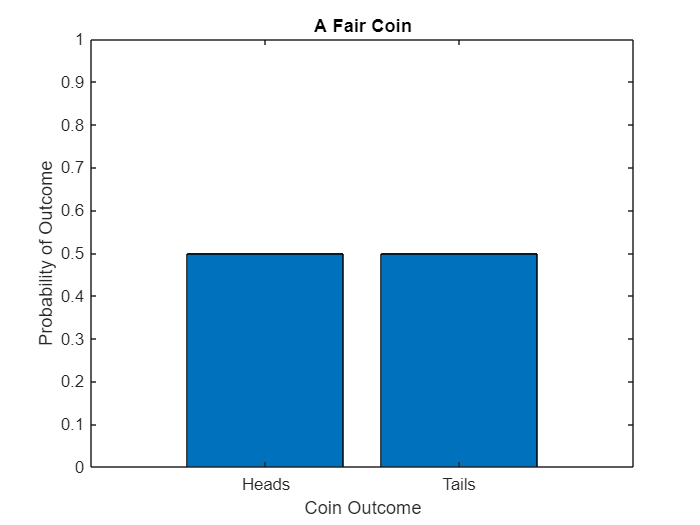

% Define a distribution

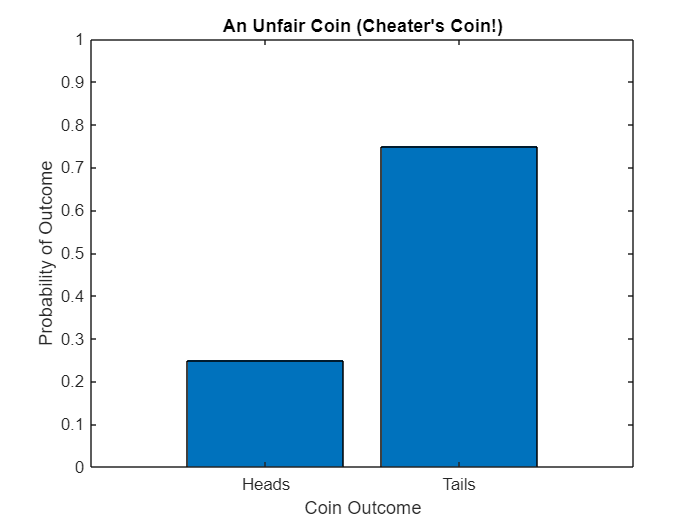

lambda = 2; % Parameter for a poisson distribution
pd = makedist('Poisson', 'lambda', lambda);
% Visualize
x = 0:10;
y = pdf(pd, x); % Generate the probabilify mass function
figure()
bar(x, y)
xlabel('Count of Infected Persons')
ylabel('Probability of Count')
title('Number of Infected persons Resulting from Patient 0')
ylim([0 1])

Like Gould talks about in "The Median Isn't The Message," the poisson distribution exhibits *right skew*. You'll practice interpreting this distribution in the next exercise.

### Exercise 4 / 5

Inspect the `Count of Infected Persons` distribution immediately above. Answer the questions below.

- What is the *most probable outcome* for the Count of Infected Persons, according to the plot above?

-  *(Write your response here) *1 or 2

- Does the the distribution look "the same" around its most probable outcome(s)? (Is it symmetric?)

- *    (Write your response here) *The probability for the 2 outcomes looks almost exactly the same.

- Is it possible for 10 people to become infected from Patient 0, according to the plot above?

-  *(Write your response here) *No

- Is it *guaranteed* that *at least one person* will become infected by Patient 0? How do you know that?

-  *(Write your response here) *No it is not because there is over a 10 percent chance that no one gets infected from patient 0.

## Useful Single Value Summaries

A probability mass function contains a lot of information: a probability value for every possibility in the sample space. We can use *summaries* to help describe a distribution (summarizing the distribution), with the added benefit that we can compare these summaries across different distributions.

Note that all of these summaries have limitations. We just talked about how a single value view of the world is foolish! However, summaries are still useful *when used appropriately*.

### Mean (Average)

The mean (aka the arithmetic mean, aka the [average](https://en.wikipedia.org/wiki/Average)) is a measure of central tendency of a distribution. This is often treated as a "typical" value, but as we saw in the Jigsaw activity earlier, just because a value is "typical" or "common," it certainly does not imply that the mean is the "true" value, or even a "likely" value.

% Define a distribution
lambda = 2;
pd = makedist('Poisson', 'lambda', lambda);
% Compute the mean
mean(pd)

The mean is *also* not the only way to define a typical value!

### Median

The [median](https://en.wikipedia.org/wiki/Median) is another measure of central tendency. The median is the "middle" of a distribution, in the sense that 50% of the distribution lies to the left of the median. This is another quantity we could use as a "typical" value, and in some cases the median will be the same as the mean:

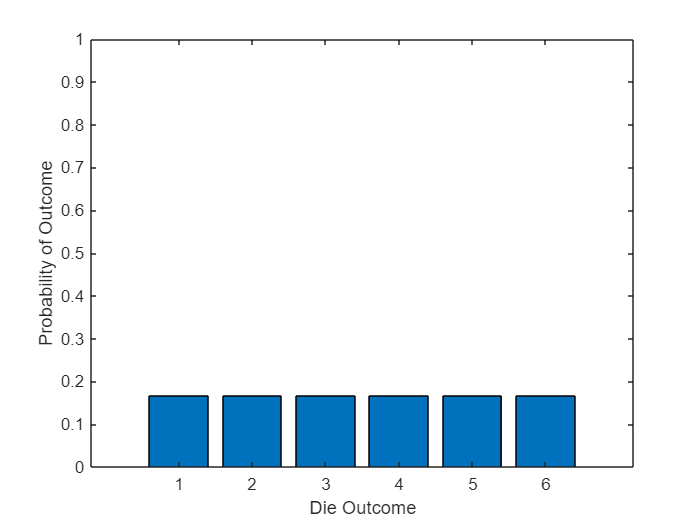

% Define a distribution
lambda = 2;
pd = makedist('Poisson', 'lambda', lambda);

% Compute the median
median(pd)

**Important note: The mean and median are generally different!**

For instance, let's look at a lognormal distribution. This is a *continuous distribution* (which we won't talk about much in ModSim), but it is an example where the mean and median are not the same value.

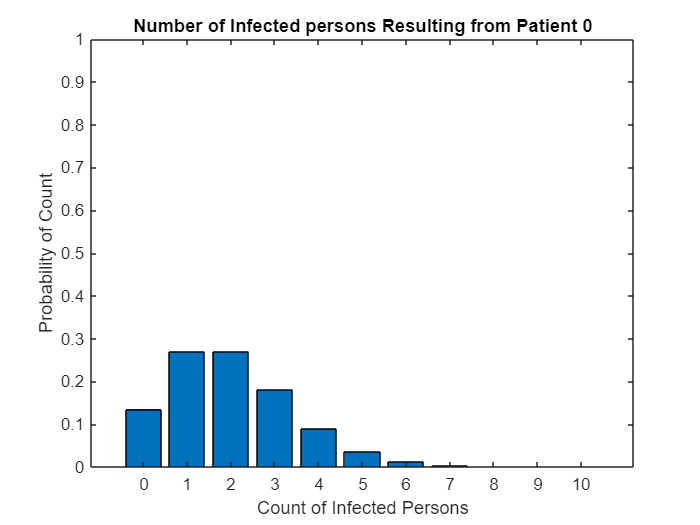

% Define a distribution
pd = makedist('Lognormal', 'mu', 1, 'sigma', 1);
% Compute mean and median
ln_mean = mean(pd);
ln_median = median(pd);
% Visualize
x = linspace(0, 10, 100);
y = pdf(pd, x);

figure()
plot(x, y, 'DisplayName', 'PDF'); hold on;
plot([ln_mean, ln_mean], [0, pdf(pd, ln_mean)], 'r', 'DisplayName', 'Mean')

plot([ln_median, ln_median], [0, pdf(pd, ln_median)], 'b', 'DisplayName', 'Median')
xlabel('Value')
ylabel('Probability Density')
legend()

This difference between mean and median is due to an important property of the median: **The median is less-affected by outlier (large) values.** 

Imagine you're in a restaurant and you compute the mean income among all the people in that building. Then imagine that Jeffrey Bezoz walks into the restaurant. The mean income will be *astronomically* different between these two cases! But the median income will only be slightly changed. This is partly why the US Census Bureau reports [median income](https://www.census.gov/library/publications/2021/demo/p60-273.html) (rather than mean income).

### Standard Deviation

The [standard deviation](https://en.wikipedia.org/wiki/Standard_deviation) is a measure of *spread*; how spread-apart the values of the random variable tend to be. 

% Define a distribution
lambda = 2;
pd = makedist('Poisson', 'lambda', lambda);
% Compute the standard deviation
std(pd)

Standard deviation has a number of uses; one of the key ones is to quantify how *variable* a random quantity is. For instance, we can compare a poisson distribution with a much larger $\lambda$ parameter:

% Define a different distribution
lambda = 10;
pd = makedist('Poisson', 'lambda', lambda);
% Compute the standard deviation
std(pd)

ans = 2

Despite having a $\lambda$ 5x the previous distribution, the new random quantity is only about 2x as variable.

To help build some intuition with these summary values, let's practice using them to interpret a given distribution.

### Exercise 5 / 5

Compute the mean, median, and standard deviation of the following distribution. Answer the questions below.

% NODE: Do not edit this
% Define a distribution to study
pd = makedist('NegativeBinomial', 'r', 1, 'p', 0.50);
x = 0:10;
y = pdf(pd, x);


ans = 2

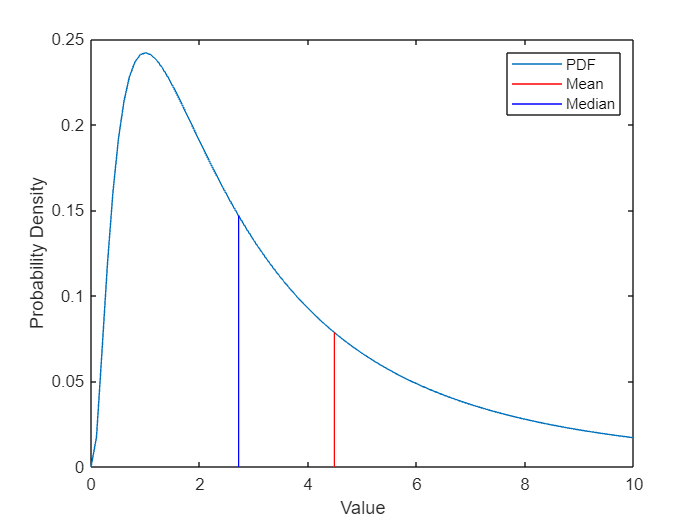

ans = 1.4142

ans = 3.1623

mean = 1

median = 0

sd = 1.4142

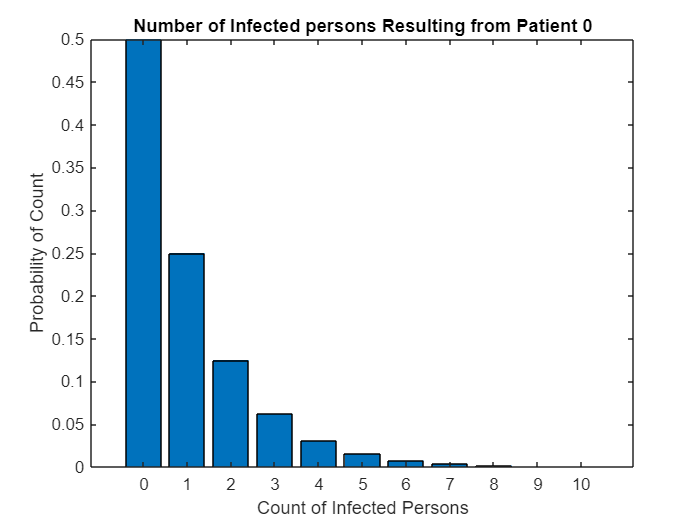

% TODO: Compute the mean, median, and standard deviation of the
% distribution
mean = mean(pd)
median = median(pd)
sd = std(pd)
% NOTE: Do not edit; use this to visualize
figure();
bar(x, y);
xlabel('Count of Infected Persons')
ylabel('Probability of Count')
title('Number of Infected persons Resulting from Patient 0')

- What is a *typical* number of people who will be infected by Patient 0?

- *    (Write your answer here) *None

- How *variable* is the number of people who will be infected by Patient 0?

- *    (Write your answer here) *1.4142

- How many people *could* be infected by Patient 0?

- *    (Write your answer here) *8

- What is the probability that one or more persons will be infected by Patient 0? How do you know this?

- *    (Write your answer here) *A little less than 25%. I know this because 1 person is the 2nd most likely amount of people to get infected, with a little less than a 25% chance of that happening.

- Imagine we assumed that every positive case led to a *typical* number of infections of other (connected) persons. How do you think this would compare with a model that uses a random number of transmissions following the distribution above?

- *    (Write your answer here) *There would be no probabilities a certain amount of people would get infected from patient 0 100% of the time.

**STOP AND DISCUSS: **Talk through these questions with your table, and jot down notes from your discussion. Ensure that everyone at your table is aligned before finishing the worksheet

## For Next Time

Before starting Worksheet 5, Part 2, download the Althouse et al. (2020) reading from Canvas and start reading the paper. Like with the Phillips (1996) paper, we will re-create some of the key results from this work. However, this time we're going to use probability theory to make sense of super-spreading events (SSE) and the transmission of SARS-CoV-2.

If you're feeling shaky on the idea of probability (or want to go deeper!), I recommend this [Khan Academy series on Probability and Statistics](https://www.youtube.com/watch?v=3v9w79NhsfI&list=PLSQl0a2vh4HCLjAoORNwUJLWi5ovMjbax). We're going to build on these ideas throughout the remainder of the worksheet. 

If you want to go deeper into the nature of uncertainty, you can check out the reading on Canvas: "Conceptual Tools for Handling Uncertainty."